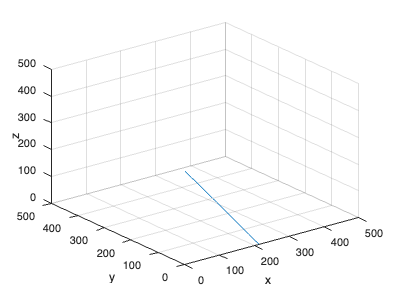

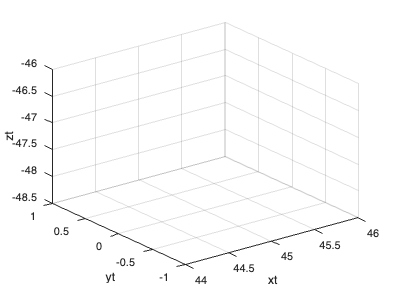

initial_position=[0; 0; 350;]; %초기 위치(X, Y) 좌표

initial_velocity=[1; 0; 0;]; %초기 속도 m/s
initial_acceleration = [3; 0; 0;]; %초기 가속도 m/s^2
gravity=9.81; %중력가속도  m/s^2

t_start=0; %시작 시간 t
t_end=20; %종료 시간 t
dt=0.01; %시간 간격(변화량)

%시간 배열 생성
t=t_start:dt:t_end;

%운동 방정식 계산
% x = initial_position(1) + initial_velocity(1) * t; 
% y = initial_position(1) + initial_velocity(2) * t.^2;
% z = initial_position(3) + initial_velocity(3) * t - 0.5 * (gravity / 2) * t.^2;

x = initial_position(1) + initial_acceleration(1) * t.^2; 
y = initial_position(1) + initial_acceleration(2) * t.^3;
z = initial_position(3) + initial_acceleration(3) * t.^2 - 0.5 * gravity * t.^2;

xt = x / t;
yt = y / t;
zt = z / t;

figure;
%그래프 그리기
plot3(x, y, z);
xlabel('x');
ylabel('y');
zlabel('z');

grid on
xlim([0 500]);
ylim([0 500]);
zlim([0 500]);

plot3(xt, yt, zt);
xlabel('xt');
ylabel('yt');
zlabel('zt');

grid on